clear
clc

load('hall.mat');
[h,w] = size(hall_gray,[1 2]);

方法1：用信息位逐一替换所有量化后DCT系数最低位，再进行熵编码

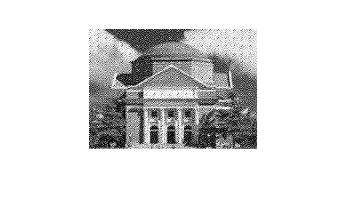

info = int32(randi([0 1],h,w));
[imgConceal,compressrate,PSNR] = DCTconceal1(hall_gray,info);
imshow(imgConceal);

infoRtv = DCTretrieve1(imgConceal);

评估信息还原的准确率

ErrorMtx = bitxor(info,infoRtv); % 按位异或得错误
fidelity = 1-sum(ErrorMtx,"all")/h/w; % 还原率

PSNR = 

compressrate =

fidelity =